# Endpoint Evolution With RW Low Voltage

## Use knm2 Uniform Fit - Stack Scans

## Thierry Lasserre, November 5 2019

## RW Settings

RWLV1 = -50;  % mV
RWLV2 = -8;   % mV
RWLV3 = +193; % mV

## General Settings

fixPar                = 'mNu E0 Bkg Norm'; % free parameter
NonPoissonScaleFactor = 1.;
range                 = 90;
RunAnaArg = {'fixPar',fixPar,'DataType','Real',...
            'FSDFlag','BlindingKNM2','ELossFlag','KatrinT2',...
            'NonPoissonScaleFactor',NonPoissonScaleFactor,...
            'AnaFlag','StackPixel','chi2','chi2Stat',...
            'RingMerge','Full'};

## Calculate E0 for : KNM2 Period 1 : rw = -50 mV (-8 mV in real? wrong grounding)

A1 = MultiRunAnalysis(RunAnaArg{:},'RingList',1:4,'RunList','KNM2_beforeFix');

-------------------Start MultiRunAnalysis Constructor----------------- 
---------------------Start RunAnalysis Constructor------------------- 
---------------------End RunAnalysis Constructor------------------- 
no new runs to convert 
ApplyStackingCuts: Exit Cut Routine after 2 Iterations 
Showing Stacked Data (data for Ring selected later) 
../../tritium-data/mat/Knm2/KNM2_beforeFix
loading response function from file: ../../inputs/ResponseFunction/samakRF_Uniform_4.2397e+17cm2_IsX3.637e-22m2_NIS7_Bm4.23T_Bs2.52T_Ba6.311G_Temin18484.100_Temax18709.096_Bin100_KatrinT2.mat


A1.exclDataStart = find(abs(range+A1.RunData.qU-18575)==min(abs(range+A1.RunData.qU-18575)));
R1 = RingAnalysis('RunAnaObj',A1,'RingList',1:4);

-------------------Start MultiRunAnalysis Constructor----------------- 
---------------------Start RunAnalysis Constructor------------------- 
---------------------End RunAnalysis Constructor------------------- 
no new runs to convert 
ApplyStackingCuts: Exit Cut Routine after 2 Iterations 
Showing Stacked Data (data for Ring selected later) 
../../tritium-data/mat/Knm2/KNM2_beforeFix
loading response function from file: ../../inputs/ResponseFunction/samakRF_Uniform_4.2397e+17cm2_IsX3.637e-22m2_NIS7_Bm4.23T_Bs2.52T_Ba6.318G_Temin18484.059_Temax18709.055_Bin100_KatrinT2.mat
-------------------Start MultiRunAnalysis Constructor----------------- 
---------------------Start RunAnalysis Constructor------------------- 
---------------------End RunAnalysis Constructor------------------- 
no new runs to convert 
ApplyStackingCuts: Exit Cut Routine after 2 Iterations 
Showing Stacked Data (data for Ring selected later) 
../../tritium-data/mat/Knm2/KNM2_beforeFix
loading response function from f

R1.FitRings('SaveResult','ON','RecomputeFlag','ON');

RunAnalysis: Loading (E0 Norm Bkg) for Initialization from file ../../tritium-data/fit/Knm2/FitResult_InitModelObj_E0NormBkg_KNM2_beforeFix.mat 
----------BEGIN FIT MINUIT-------------- 
  MINUIT RELEASE 96.03  INITIALIZED.   DIMENSIONS 150/150  EPSMAC=  0.89E-15

 PARAMETER DEFINITIONS:
    NO.   NAME         VALUE      STEP SIZE      LIMITS
     1 'Par  #1   '    0.0000      0.10000E-04     no limits
     2 'Par  #2   '    0.0000      0.10000E-04     no limits
     3 'Par  #3   '  -0.28211      0.28211E-02     no limits
     4 'Par  #4   '   0.54735E-01  0.54735E-03     no limits
     5 'Par  #5   '    0.0000      0.10000E-04     no limits
     6 'Par  #6   '    0.0000      0.10000E-04     no limits
     7 'Par  #7   '    0.0000      0.10000E-04     no limits
     8 'Par  #8   '    0.0000      0.10000E-04     no limits
     9 'Par  #9   '    0.0000      0.10000E-04     no limits
    10 'Par #10   '    0.0000      0.10000E-04     no limits
    11 'Par #11   '    0.0000      0.10000E-0

% E0P1  = R1.FitResult.par(:,2)+A1.ModelObj.Q_i;
% E0P1E = R1.FitResult.err(:,2);

## Calculate E0 for : KNM2 Period 2 : rw = -8mV  (+42 mV in principle)

A2 = MultiRunAnalysis(RunAnaArg{:},'RingList',1:4,'RunList','KNM2_afterFix');

-------------------Start MultiRunAnalysis Constructor----------------- 
---------------------Start RunAnalysis Constructor------------------- 
---------------------End RunAnalysis Constructor------------------- 
no new runs to convert 
ApplyStackingCuts: Exit Cut Routine after 1 Iterations 
Showing Stacked Data (data for Ring selected later) 
../../tritium-data/mat/Knm2/KNM2_afterFix
loading response function from file: ../../inputs/ResponseFunction/samakRF_Uniform_4.2489e+17cm2_IsX3.637e-22m2_NIS7_Bm4.23T_Bs2.52T_Ba6.311G_Temin18484.087_Temax18709.095_Bin100_KatrinT2.mat


A2.exclDataStart = find(abs(range+A1.RunData.qU-18575)==min(abs(range+A1.RunData.qU-18575)));
R2 = RingAnalysis('RunAnaObj',A2,'RingList',1:4);

-------------------Start MultiRunAnalysis Constructor----------------- 
---------------------Start RunAnalysis Constructor------------------- 
---------------------End RunAnalysis Constructor------------------- 
no new runs to convert 
ApplyStackingCuts: Exit Cut Routine after 1 Iterations 
Showing Stacked Data (data for Ring selected later) 
../../tritium-data/mat/Knm2/KNM2_afterFix
loading response function from file: ../../inputs/ResponseFunction/samakRF_Uniform_4.2489e+17cm2_IsX3.637e-22m2_NIS7_Bm4.23T_Bs2.52T_Ba6.318G_Temin18484.046_Temax18709.054_Bin100_KatrinT2.mat
-------------------Start MultiRunAnalysis Constructor----------------- 
---------------------Start RunAnalysis Constructor------------------- 
---------------------End RunAnalysis Constructor------------------- 
no new runs to convert 
ApplyStackingCuts: Exit Cut Routine after 1 Iterations 
Showing Stacked Data (data for Ring selected later) 
../../tritium-data/mat/Knm2/KNM2_afterFix
loading response function from fil

R2.FitRings('SaveResult','ON','RecomputeFlag','ON');

RunAnalysis: Loading (E0 Norm Bkg) for Initialization from file ../../tritium-data/fit/Knm2/FitResult_InitModelObj_E0NormBkg_KNM2_afterFix.mat 
----------BEGIN FIT MINUIT-------------- 
  MINUIT RELEASE 96.03  INITIALIZED.   DIMENSIONS 150/150  EPSMAC=  0.89E-15

 PARAMETER DEFINITIONS:
    NO.   NAME         VALUE      STEP SIZE      LIMITS
     1 'Par  #1   '    0.0000      0.10000E-04     no limits
     2 'Par  #2   '    0.0000      0.10000E-04     no limits
     3 'Par  #3   '  -0.28046      0.28046E-02     no limits
     4 'Par  #4   '   0.61593E-01  0.61593E-03     no limits
     5 'Par  #5   '    0.0000      0.10000E-04     no limits
     6 'Par  #6   '    0.0000      0.10000E-04     no limits
     7 'Par  #7   '    0.0000      0.10000E-04     no limits
     8 'Par  #8   '    0.0000      0.10000E-04     no limits
     9 'Par  #9   '    0.0000      0.10000E-04     no limits
    10 'Par #10   '    0.0000      0.10000E-04     no limits
    11 'Par #11   '    0.0000      0.10000E-04

  m^2       = 0.325711 +/- 0.0181471 eV^2
  m         = 0.570711 +/- 0.0156832 eV
 - - - - - - - - - - - - - - - - - - - - - - - 
  (E0)eff   = 18573.6947 +/- 0.007553 eV
 - - - - - - - - - - - - - - - - - - - - - - - 
  B         = 35.7878 +/- 0.550114 mcps (19 pixels) 
 - - - - - - - - - - - - - - - - - - - - - - - 
  N         = 0.915814 +/- 0.000755583
Table 'Fit Results  - Fitter = minuit':
Parameter	 | Value	 | Uncertainty	 | Unit
m^2_\beta	 | 0.33		 | 0.02		 | eV^2
E_{0,eff}	 | 18573.69	 | 0.01		 | eV
Background	 | 35.79	 | 0.55		 | mcps
Normalization	 | 0.92		 | 0.00		 | 
		 | 		 | 		 | 
\chi^2		 | dof		 | 		 | pvalue
17.21		 | 34.00	 | 		 | 0.993
% PrintTable "Fit Results  - Fitter = minuit - Range = [18484.1 - 18709.1] eV" generated on 12-Nov-2019 08:42:08
% Created in FITC.displayresults:643 at /Users/thierrylasserre1/Samak2.0/fitting/FITC.m
% Export settings: TexMathModeDetection 1, HasHeader 1, HasRowHeader 0, StripInsertedTabChars 1, IsPDF 0, TightPDF 1
\begin{table}[!hb]

% E0P2  = R2.FitResult.par(:,2)+A2.ModelObj.Q_i;
% E0P2E = R2.FitResult.err(:,2);

## Calculate E0 for : KNM2 Period 3 : rw = +193 mV

A3 = MultiRunAnalysis(RunAnaArg{:},'RingList',1:4,'RunList','KNM2_after2ndFix');

-------------------Start MultiRunAnalysis Constructor----------------- 
---------------------Start RunAnalysis Constructor------------------- 
---------------------End RunAnalysis Constructor------------------- 
no new runs to convert 
ApplyStackingCuts: Exit Cut Routine after 1 Iterations 
Showing Stacked Data (data for Ring selected later) 
../../tritium-data/mat/Knm2/KNM2_after2ndFix
loading response function from file: ../../inputs/ResponseFunction/samakRF_Uniform_4.2531e+17cm2_IsX3.637e-22m2_NIS7_Bm4.23T_Bs2.52T_Ba6.311G_Temin18484.094_Temax18709.097_Bin100_KatrinT2.mat


A3.exclDataStart = find(abs(range+A1.RunData.qU-18575)==min(abs(range+A1.RunData.qU-18575)));
R3 = RingAnalysis('RunAnaObj',A3,'RingList',1:4);

-------------------Start MultiRunAnalysis Constructor----------------- 
---------------------Start RunAnalysis Constructor------------------- 
---------------------End RunAnalysis Constructor------------------- 
no new runs to convert 
ApplyStackingCuts: Exit Cut Routine after 1 Iterations 
Showing Stacked Data (data for Ring selected later) 
../../tritium-data/mat/Knm2/KNM2_after2ndFix
loading response function from file: ../../inputs/ResponseFunction/samakRF_Uniform_4.2531e+17cm2_IsX3.637e-22m2_NIS7_Bm4.23T_Bs2.52T_Ba6.318G_Temin18484.052_Temax18709.056_Bin100_KatrinT2.mat
-------------------Start MultiRunAnalysis Constructor----------------- 
---------------------Start RunAnalysis Constructor------------------- 
---------------------End RunAnalysis Constructor------------------- 
no new runs to convert 
ApplyStackingCuts: Exit Cut Routine after 1 Iterations 
Showing Stacked Data (data for Ring selected later) 
../../tritium-data/mat/Knm2/KNM2_after2ndFix
loading response function fr

R3.FitRings('SaveResult','ON','RecomputeFlag','ON');

RunAnalysis: Loading (E0 Norm Bkg) for Initialization from file ../../tritium-data/fit/Knm2/FitResult_InitModelObj_E0NormBkg_KNM2_after2ndFix.mat 
----------BEGIN FIT MINUIT-------------- 
  MINUIT RELEASE 96.03  INITIALIZED.   DIMENSIONS 150/150  EPSMAC=  0.89E-15

 PARAMETER DEFINITIONS:
    NO.   NAME         VALUE      STEP SIZE      LIMITS
     1 'Par  #1   '    0.0000      0.10000E-04     no limits
     2 'Par  #2   '    0.0000      0.10000E-04     no limits
     3 'Par  #3   '  -0.27848      0.27848E-02     no limits
     4 'Par  #4   '   0.61541E-01  0.61541E-03     no limits
     5 'Par  #5   '    0.0000      0.10000E-04     no limits
     6 'Par  #6   '    0.0000      0.10000E-04     no limits
     7 'Par  #7   '    0.0000      0.10000E-04     no limits
     8 'Par  #8   '    0.0000      0.10000E-04     no limits
     9 'Par  #9   '    0.0000      0.10000E-04     no limits
    10 'Par #10   '    0.0000      0.10000E-04     no limits
    11 'Par #11   '    0.0000      0.10000E

% E0P3  = R3.FitResult.par(:,2)+A3.ModelObj.Q_i;
% E0P3E = R3.FitResult.err(:,2);

## Display - E0 ring-wise for the 3 periods

  MINUIT RELEASE 96.03  INITIALIZED.   DIMENSIONS 150/150  EPSMAC=  0.89E-15

 PARAMETER DEFINITIONS:
    NO.   NAME         VALUE      STEP SIZE      LIMITS
     1 'Par  #1   '    0.0000      0.10000E-04     no limits
     2 'Par  #2   '    0.0000      0.10000E-04     no limits


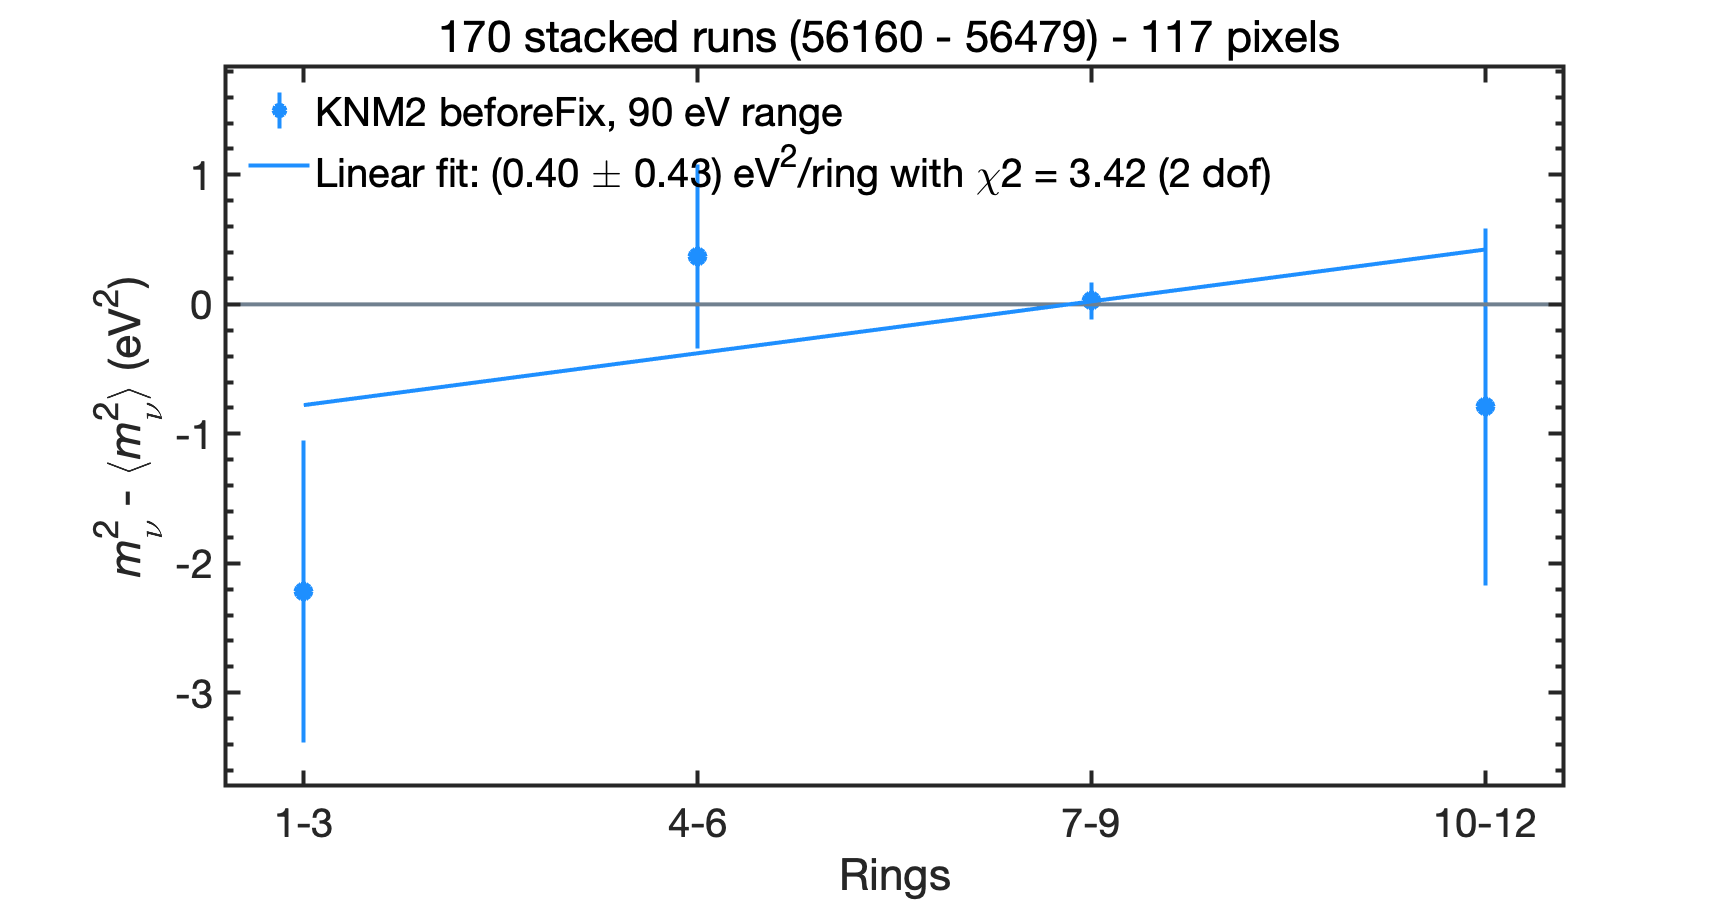

Save plot to ../../tritium-data/plots/Knm2/RingFit/m2_ringwise_KNM2_beforeFixRuns_90range_Full_Merge_5678910111213_Real_BlindON.pdf 


R1.PlotFits('SavePlot','ON','Blind','ON','PlotPar',1);

  MINUIT RELEASE 96.03  INITIALIZED.   DIMENSIONS 150/150  EPSMAC=  0.89E-15

 PARAMETER DEFINITIONS:
    NO.   NAME         VALUE      STEP SIZE      LIMITS
     1 'Par  #1   '    0.0000      0.10000E-04     no limits
     2 'Par  #2   '    0.0000      0.10000E-04     no limits


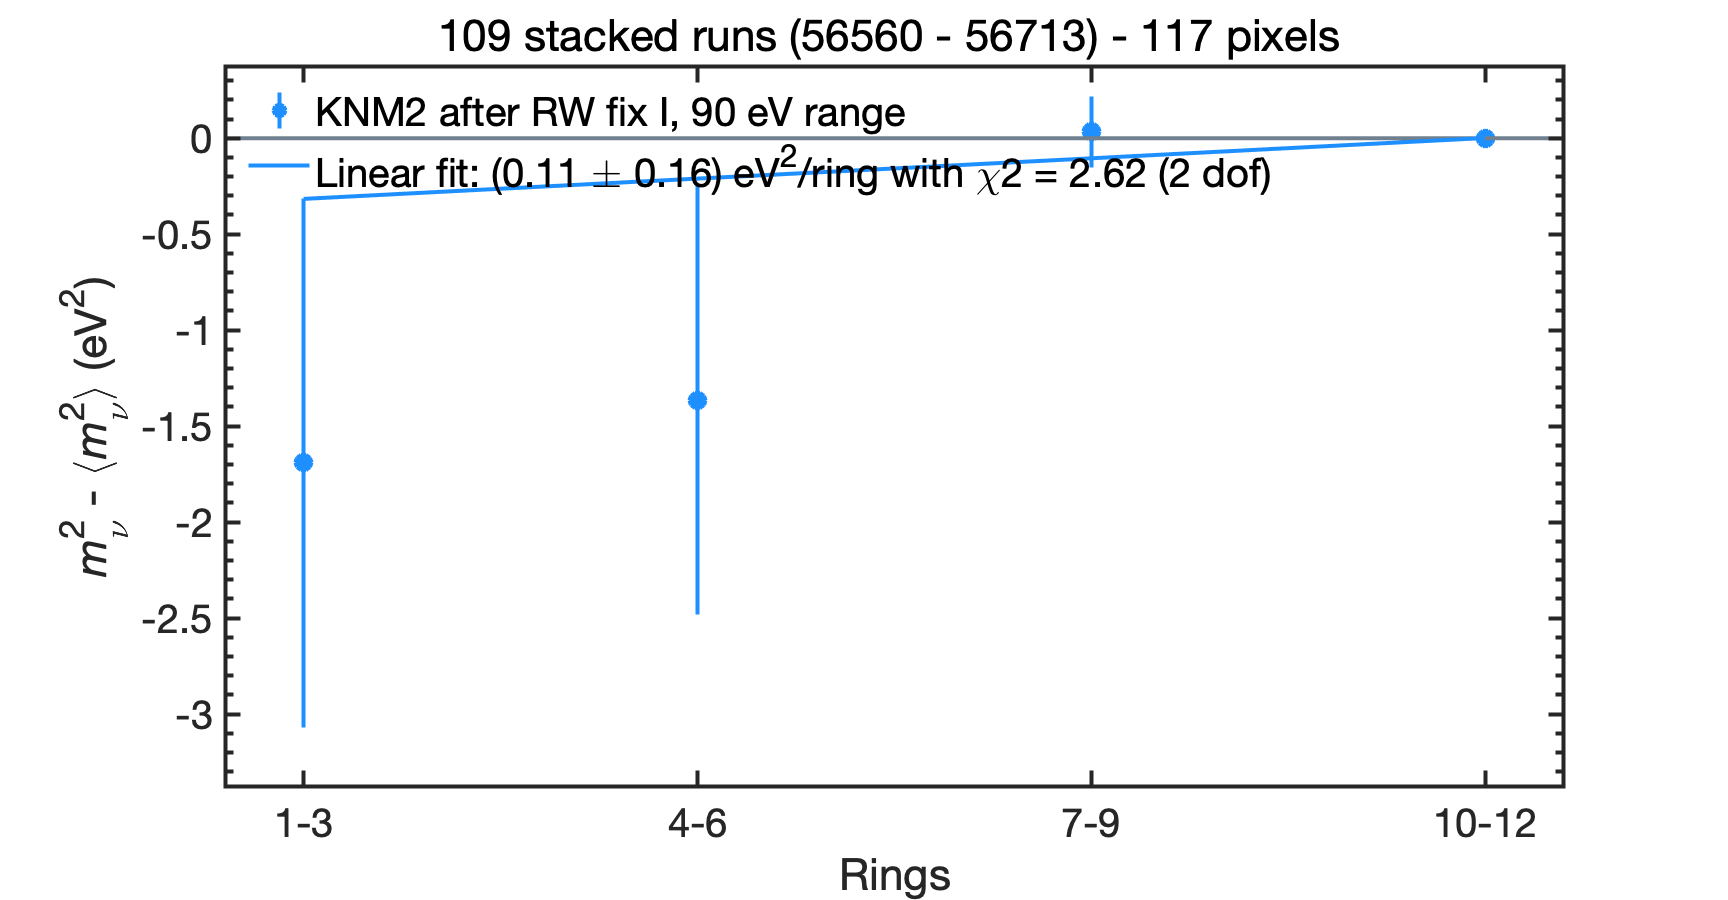

Save plot to ../../tritium-data/plots/Knm2/RingFit/m2_ringwise_KNM2_afterFixRuns_90range_Full_Merge_5678910111213_Real_BlindON.pdf 


R2.PlotFits('SavePlot','ON','Blind','ON','PlotPar',1);

  MINUIT RELEASE 96.03  INITIALIZED.   DIMENSIONS 150/150  EPSMAC=  0.89E-15

 PARAMETER DEFINITIONS:
    NO.   NAME         VALUE      STEP SIZE      LIMITS
     1 'Par  #1   '    0.0000      0.10000E-04     no limits
     2 'Par  #2   '    0.0000      0.10000E-04     no limits


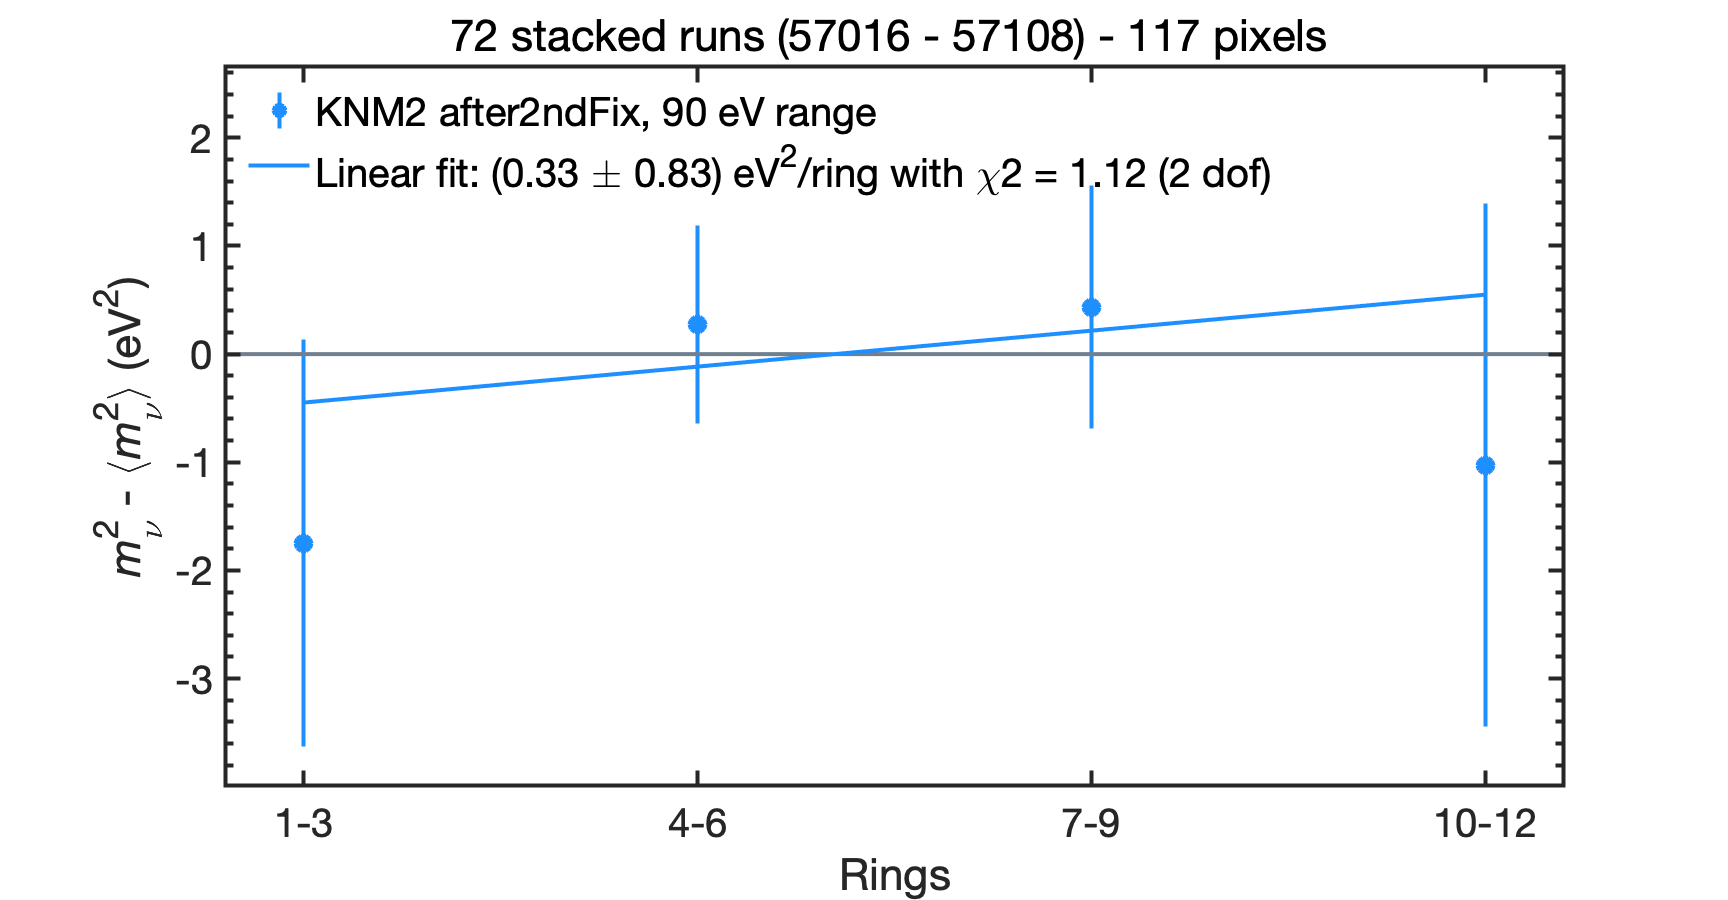

Save plot to ../../tritium-data/plots/Knm2/RingFit/m2_ringwise_KNM2_after2ndFixRuns_90range_Full_Merge_5678910111213_Real_BlindON.pdf 


R3.PlotFits('SavePlot','ON','Blind','ON','PlotPar',1); 

return;

## Display - E0 Versus RW voltage, for each ring 

## Period3 - Period2

RWLV     = [RWLV2-RWLV2 RWLV3-RWLV2];
RWE0R1   = [ E0P2(1) E0P3(1)]-E0P2(1); 
RWE0R2   = [ E0P2(2) E0P3(2)]-E0P2(2); 
RWE0R3   = [ E0P2(3) E0P3(3)]-E0P2(3); 
RWE0R4   = [ E0P2(4) E0P3(4)]-E0P2(4); 

RWE0R1E   = [ E0P2E(1) E0P3E(1)];
RWE0R2E   = [ E0P2E(2) E0P3E(2)];
RWE0R3E   = [ E0P2E(3) E0P3E(3)];
RWE0R4E   = [ E0P2E(4) E0P3E(4)];

hr1 = errorbar(RWLV,RWE0R1*1e3,RWE0R1E*1e3,'s--','LineWidth',2,'Color','Red','MarkerSize',18);
hold on
hr2 = errorbar(RWLV,RWE0R2*1e3,RWE0R2E*1e3,'s--','LineWidth',2,'Color','Blue','MarkerSize',18);
hr3 = errorbar(RWLV,RWE0R3*1e3,RWE0R3E*1e3,'s--','LineWidth',2,'Color','Green','MarkerSize',18);
hr4 = errorbar(RWLV,RWE0R4*1e3,RWE0R4E*1e3,'s--','LineWidth',2,'Color','Magenta','MarkerSize',18);
he=line([RWLV],[-RWLV],'LineStyle','-.','Color','Black','LineWidth',4);
hold off
legend('boxoff');
ylabel('\Delta E_0 (meV)','FontSize',24); 
xlabel({'RW Low Voltage Shift (mV)'});
legend([ hr1 hr2 hr3 hr4 he],'SPRring1','SPRring2','SPRring3','SPRring4','Perfect Coupling',...
    'Location','SouthWest','FontSize',24)
grid off
PrettyFigureFormat('FontSize',24); 
ax = gca;ax.YAxisLocation = 'right';
xlim([min(RWLV)-15 max(RWLV)+15]);
